## Objectives: 

- Creating and manipulating matrix

- Matrix Arithmetique

- Plotting graphs and working with matlab built in functions (exp,log,sqrt)

- Tasks

## Matrix:

### Introduction:

Variables that we created so far can old only 1 values but 

### Creating matrix:

There is 3 types of matrix

#### Column matrix

This matrix represent horizontal vectuer to create it we use

first_matrix=[1; 2; 3; 4]

#### Ligne matrix

This matrix represent vertical vecture to create it we use 

second_matrix = [1, 2, 3, 4]
% or we can use
second_matrix2 = [1 2 3 4]

#### Remarque:

we can notice then when we want go to fill next column on matrix we use space or , and when we want to fix next ligne we use ;

#### Rectangulair matrix

It matrix of shape (n*m) we can create it using

third_matrix = [1 2 3;4 5 6;7 8 9]

### Accessing elements of matrix

To access the elements of matrix we use the indexing method, first element have index 0 and so on , for column and ligne matrix 1 index is enough , for recungulaire matrix we use double indexing method first index represent lignes second index represent column

matrix_1=[1; 2; 3; 4]
disp(matrix_1(3)) % This will display the third element which is 3
matrix_2 = [1, 2, 3, 4] 
disp(matrix_2(1))  % This will display the first element which is 1
matrix_3 = [1 2 3;4 5 6;7 8 9]
disp(matrix_3(2,3)) % This will display the third elemetn of the second line which is 6

## Matrix Arithmetique

### Addition and Soustraction

If 2 matrix have same size we can add or soustract  them  using + -

matrix_a = [4 5;6 0];
matrix_b = [1 2;3 2];
matrix_c = matrix_a + matrix_b;
matrix_d = matrix_a - matrix_b;
disp(matrix_c);
disp(matrix_d);

### Remarque

to calculate the size of matrix we use the function size() it will return 2 numbers first one represent number of lines second one represent number of column.

a = [4 5 3;6 0 2];
a_size = size(a);
disp(a_size)

### Multiplication And division:

### Multiplication:

there is 3 types of multiplication 

- multiplying matrix by number we just do n * M

- multiplying elements of 2 matrix together, the 2 matrix should have same size we do M1.*M2 it same for division to divide element by element we use M1./M2, to calculate the square of each element inside matrix we can do M.*M or we can do M.^2

- multiplication matricielle number of column of first matrix should equal number of line of second one we do M1*M2

n = 5;
M1 = [1 2;3 2];
M2 = [4 9;7 8];
M3 = [2 5;4 3;2 1];
m1 = n * M1;
m2 = M1 .* M2;
m3 = M3 * M1;
m4 = M3 .^ 2
disp("m1 : ");
disp(m1);
disp("m2 : ");
disp(m2);
disp("m3 : ");
disp(m3);
disp("m4 : ");
disp(m4);
disp("m5 : ");
disp(m5);

### Division:

we have also 3 type of division

- dividig matrix by number we just do  M / n

- dividing elements of 2 matrix together, the 2 matrix should have same size we do M1./M2

- division of 2 matrix M1/M2 and in this case it will calculate M1*Inv(M2)

n = 5;
M1 = [1 2;3 2];
M2 = [4 9;7 8];
M3 = [2 5;4 3;2 1];
m1 = M1 / n;
m2 = M1 ./ M2;
m3 = M2 / M1;
disp("m1 : ");
disp(m1);
disp("m2 : ");
disp(m2);
disp("m3 : ");
disp(m3);


### Inverse and determinant of matrix

We calculate determinant of matrix using **det(m1)** , if determinant isn't null we can calculate the inverse of m1

to calculate determinant and inverse the matrix should be square number of column is equal number of lines 

There is 2 methods to calculate inverse of matrix:

- using the command inv()

- using  m1^(-1)

m = [4 5;5 3];
d = det(m);
inverse1 = inv(m);
inverse2= m^(-1);
disp("determinant : ");
disp(d);
disp("inverse method 1 :");
disp(inverse1);
disp("inverse method 2 :");
disp(inverse2);

**Remarques**

- Matrix M multiplied by it inverse will give use identity matrix I

- Matrix identity I is like 1 any matrix multiplied by this matrix will stay same M*I=M

### Create interval of value

Sometimes we need to create matrix column of element betteween 2 numbers lets suppose we want to create matrix column that have all numbers from -10 to 10 we can do it as we saw before but when the low and uppper bar of the interval change this become more difficile to fix that matlab provide us with way to do it using

 m = start:end the default step between each value is 1 to change that we can add the step so it become m = start:step:end

first_interval = 4:20; 
second_interval = 0:0.1:5;
disp("first interval");
disp(first_interval);
disp("second interval");
disp(second_interval);

### Slice and combine matrix

#### Slicing matrix

We use slicing to get sub matrix from a parrent matrix to get slice from a matrix we use iterval instead nrml index , for the interval we set start and end

parrent_matrix = [4 5 8 9;4 5 8 9;4 5 8 9;4 5 8 9;4 5 8 9;4 5 8 9];
child_matrix = parrent_matrix(1:3,2:3);
disp("child matrix is :");
disp(child_matrix);

#### Combine matrix together

There is 2 way to combine matrix

- vertical combine they should have same number of lines we just do m = [m1 m2]

- horizontal combine they should have same number of column we do that by using m = [m1;m2]

M_1 = [4 5];
M_2 = [3 2;4 8];
M_3 = [M_1;M_2];
disp("Vertical combine of M_1 and M_2");
disp(M_3)
m_1 = [3 2;4 8];
m_2 = [3 2 6 9 10 11;4 8 3 2 8 7];
m_3 = [m_1 m_2];
disp("Horizontal combine of m_1 and m_2");
disp(m_3)

### Transpose of matrix and some special matrix

Transpose of matrix is inversing lines and column that mean we turn lines to columns and column to lines we do that using : ' or tanspose()

Matrixe identite is square matrix that have 1 and it diagonal and 0 else where we create it using eyes()

Matrix of ones is matrix that full of ones we create it using onese(n,m) n is number of lines and m numbers of column , if it is suqre we can do ones(m)

Matrix of zeros is matrix that full of zeros we create it using zeros(n,m) n is number of lines and m numbers of column , if it is suqre we can do zeros(m)

Finally to get the diagonal of matrix we use diag()

G = [4 5 1;2 5 0;4 2 3]
G_t = G'
G_T = transpose(G)
identity_matrix = eye(5)
matrix_of_zeros = zeros(4,5)
matrix_of_ones = ones(4,5)
diagonal = diag(G)

## Working with Graph

we saw so far how to work with matrix and how to work with data ow it time to see this data, matab have many tools that help to visualise data and one of them is plots

## Ploting simple functions

lets suppose we have the followig function 


$${f\left(x\right)=x}^2$$
  

The steps to draw this function are as follow :

- Create variable x represent the interval that we want to draw our function in

- Calculate y

- Using plot to draw the function

- Adding title to the figure and titles for each axis and a legend

x = -10:0.1:10;
y = x .^ 2;
plot(x,y);
title("Y = X^2")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("y = x ^ 2")

## Plotting multiple graph in same figure

There is 2 way to plot graph in same figure :

### Method 1 Hold on

By using the keyword **hold on**  matlab to keep the current graph and draw the new graph in top of it

x = -10:0.1:10;
y1 = 5 * x + 6;
y2 = 2 * x;
plot(x,y1)
hold on;
plot(x,y2)
title(" plotting using hold on")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("5 * x + 6","2 * x")

#### Dividing the figure

The other method to plot graph in same figure is by dividing the figure to many subfigure we use this by using the function subplot(n,m,p)

- n is number of lines that will figure  will be divides by

- m is number of column that will figure  will be divides by

- p position where we want to put our subplot counting start from top left till bottom right

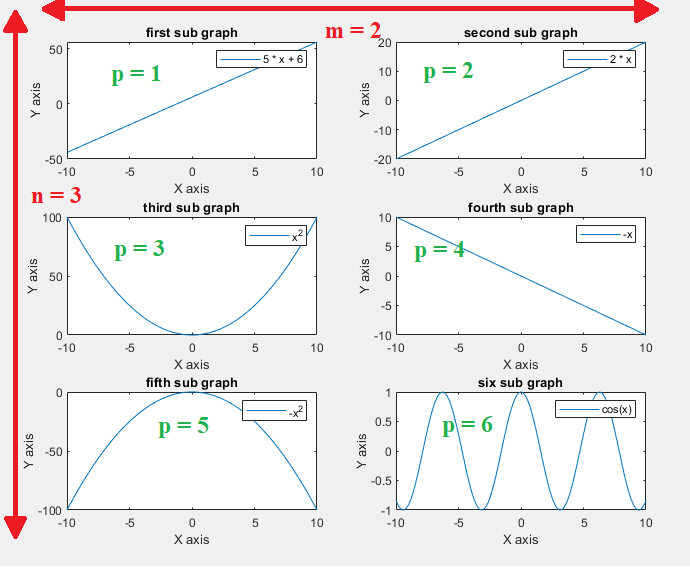

x = -10:0.1:10;
y1 = 5 * x + 6;
y2 = 2 * x;
y3 = x .^ 2;
y4 = -x;
y5 = -x .^ 2;
y6 = cos(x);

subplot(3,2,1)
plot(x,y1)
title(" first sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("5 * x + 6")
subplot(3,2,2)
plot(x,y2)
title(" second sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("2 * x")
subplot(3,2,3)
plot(x,y3)
title(" third sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("x^2")
subplot(3,2,4)
plot(x,y4)
title(" fourth sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("-x")
subplot(3,2,5)
plot(x,y5)
title(" fifth sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("-x^2")
subplot(3,2,6)
plot(x,y6)
title(" six sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("cos(x)")

## Ploting Graph in diffirent figures

Last way to plot multiple graph is using deffirent figures for each graph , to do what all what we need to do is using the function **figure()** inside it number of the figure

x = -10:0.1:10;
y1 = 5 * x + 6;
y2 = 2 * x;
figure(1)
plot(x,y1)
title(" first sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("5 * x + 6")
figure(2)
plot(x,y2)
title(" second sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("2 * x")

### Remarque

we can costumize plot for example changing color and plot using stars instead of line ...

x = -10:1:10;
y1 = 5 * x + 6;
y2 = 2 * x;
figure(1)
plot(x,y1,'r*')
title(" first sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("5 * x + 6")
figure(2)
plot(x,y2,'ro')
title(" second sub graph ")
xlabel(" X axis ")
ylabel(" Y axis ")
legend("2 * x")

This table of costumization parametres and what they do

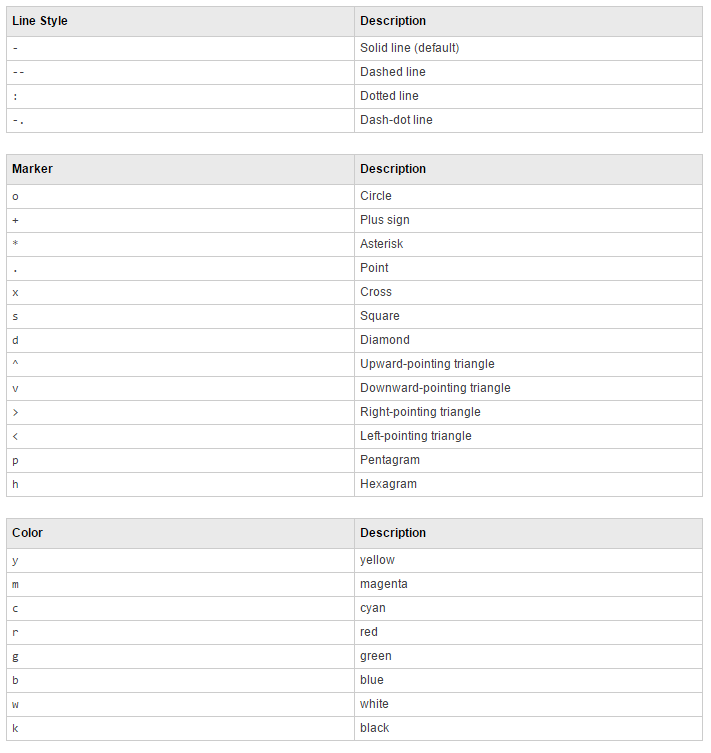

## Tasks :

### Task 1 :

Using graph and interval from -20 to 20 solve this function


$$\begin{array}{l}
f\left(x\right)=x^2 \\
g\left(x\right)=3x+4\\
f\left(x\right)<g\left(x\right)
\end{array}$$


%Solution

### Task 2 : 

We Have the following circuit and the systemes of equation that each maile represent , using matrix arithmetique find **i1** and **i2**


$$E=5\;v,R=2\Omega ,\mathrm{R1}=5\Omega \;,\mathrm{R2}=7\Omega$$


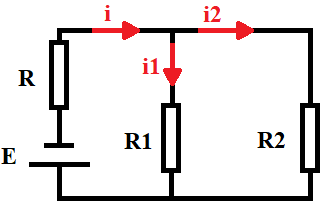


$$\begin{array}{l}
i=\mathrm{i1}+\mathrm{i2}\\
E=\mathrm{Ri}+\mathrm{R1i1}\\
E=\mathrm{Ri2}+\mathrm{R2i2}\\
\mathrm{using}\;\mathrm{the}\;\mathrm{first}\;\mathrm{equation}\;\mathrm{we}\;\mathrm{can}\;\mathrm{say}\\
E=R\left(\mathrm{i1}+\mathrm{i2}\right)+\mathrm{R1i1}\\
E=R\left(\mathrm{i1}+\mathrm{i2}\right)+\mathrm{R2i2}\\
\mathrm{the}\;\mathrm{final}\;\mathrm{restult}\;\mathrm{become}:\\
E=\mathrm{Ri2}+\left(\mathrm{R1}+R\right)\mathrm{i1}\\
E=\mathrm{Ri1}+\left(\mathrm{R2}+R\right)\mathrm{i2}\\
\mathrm{we}\;\mathrm{will}\;\mathrm{get}\;\mathrm{this}\;\mathrm{system}\;\mathrm{of}\;\mathrm{equations}:\\
5=2*\mathrm{i2}+7*\mathrm{i1}\\
5=2*\mathrm{i1}+9*\mathrm{I2}
\end{array}$$


#### Hint:

When we have system of equations we can use the matrix representation of the system as follow


$$\begin{array}{l}
2x+3y=5\\
x+7y=6\\
\left\lbrack \begin{array}{cc}
2 & 3\\
1 & 7
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
5\\
6
\end{array}\right\rbrack \\
\mathrm{Where}\;\\
A=\left\lbrack \begin{array}{cc}
2 & 3\\
1 & 7
\end{array}\right\rbrack \\
X=\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \\
B=\left\lbrack \begin{array}{c}
5\\
6
\end{array}\right\rbrack \\
\mathrm{we}\;\mathrm{will}\;\mathrm{get}\;\\
\mathrm{AX}=B\\
A^{-1} \mathrm{AX}=A^{-1} B\\
X=A^{-1} B
\end{array}$$


% Solution
